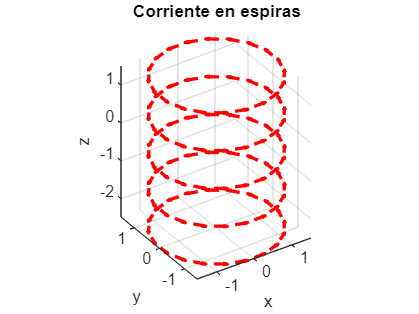

% Simulación del campo magnético de un solenoide usando la ley de Biot-Savart
clear
clc
clf

%-------------------- PARTE 1: DEFINICIÓN DE LA ESPIRA --------------------
num_espiras = 5;                      % Número de espiras
puntos_por_espira = 20;               % Puntos por espira
radio_espira = 1.5;                   % Radio de cada espira
espaciado_z = 1;                      % Separación entre espiras (paso en Z)
corriente = 300;                      % Corriente (A)
mu0 = 4*pi*1e-7;                      % Permeabilidad magnética del vacío
constante_BS = mu0 * corriente / (4*pi); % Constante de Biot–Savart
radio_seguro = 0.2;                   % Grosor efectivo del alambre para evitar singularidades

% Ángulo para cada punto sobre la espira
delta_theta = 2*pi / puntos_por_espira;
theta_vals = 0:delta_theta:(2*pi - delta_theta);

% Inicialización de posiciones e incrementos
idx = 1;
for n = 1:num_espiras
    pos_x(idx:idx+puntos_por_espira-1) = radio_espira * cos(theta_vals);
    pos_y(idx:idx+puntos_por_espira-1) = radio_espira * sin(theta_vals);
    pos_z(idx:idx+puntos_por_espira-1) = -num_espiras/2*espaciado_z + (n-1)*espaciado_z;

    vec_x(idx:idx+puntos_por_espira-1) = -pos_y(idx:idx+puntos_por_espira-1) * delta_theta;
    vec_y(idx:idx+puntos_por_espira-1) =  pos_x(idx:idx+puntos_por_espira-1) * delta_theta;

    idx = idx + puntos_por_espira;
end
vec_z = zeros(1, puntos_por_espira*num_espiras);

% Visualización de la espira
figure(1);
quiver3(pos_x, pos_y, pos_z, vec_x, vec_y, vec_z, 0.5, '-r', 'LineWidth', 2);
view(-34, 33);
title('Corriente en espiras');
xlabel('x'); ylabel('y'); zlabel('z');
axis equal;


%-------------------- PARTE 2: CAMPO MAGNÉTICO --------------------
% Definición del espacio de cálculo
paso_espacio = 0.1;
eje_x = -5:paso_espacio:5;
eje_y = eje_x;
eje_z = eje_x;
len_x = length(eje_x);
len_y = length(eje_y);
len_z = length(eje_z);

% Inicialización de los componentes del campo
campo_x = zeros(len_x, len_y, len_z);
campo_y = zeros(len_x, len_y, len_z);
campo_z = zeros(len_x, len_y, len_z);

% Cálculo del campo en cada punto del espacio
tic
for ix = 1:len_x
    for iy = 1:len_y
        for iz = 1:len_z
            for iw = 1:num_espiras*puntos_por_espira
                rx = eje_x(ix) - pos_x(iw);
                ry = eje_y(iy) - pos_y(iw);
                rz = eje_z(iz) - pos_z(iw);

                r_norm = sqrt(rx^2 + ry^2 + rz^2 + radio_seguro^2);
                r_cubed = r_norm^3;

                % Ley de Biot–Savart
                campo_x(ix,iy,iz) = campo_x(ix,iy,iz) + constante_BS * vec_y(iw) * rz / r_cubed;
                campo_y(ix,iy,iz) = campo_y(ix,iy,iz) + constante_BS * vec_x(iw) * rz / r_cubed;
                campo_z(ix,iy,iz) = campo_z(ix,iy,iz) + constante_BS * (vec_x(iw) * ry - vec_y(iw) * rx) / r_cubed;
            end
        end
    end
end
toc

Elapsed time is 15.693688 seconds.



% Magnitud del campo
magnitud_campo = sqrt(campo_x.^2 + campo_y.^2 + campo_z.^2);

% Corte en el plano XZ (y = 0)
plano_medio_x = ceil(len_x / 2);
plano_medio_y = ceil(len_y / 2);
campo_x_xz = squeeze(campo_x(plano_medio_x, plano_medio_y, :));
campo_z_xz = squeeze(campo_z(plano_medio_x, plano_medio_y, :));
campo_magnitud_xz = squeeze(magnitud_campo(plano_medio_x, plano_medio_y, :));

% Visualización del campo
figure(2); clf
pcolor(eje_x, eje_z, (campo_magnitud_xz').^(1/3)); 

Error using pcolor (line 21)
Matrix dimensions must agree.

shading interp; colormap jet; colorbar

% [XX, ZZ] = meshgrid(eje_x, eje_z);
% streamplot = streamslice(XX, ZZ, campo_x_xz', campo_z_xz', 3);
% set(streamplot, 'Color', [0.8 1 0.9]);

% xlabel('x'); ylabel('z');
% title('Campo magnético generado por un solenoide')







z_pos = linspace(-5.2,5.2,101);

Bz_forward = interp1(z_pos,campo_magnitud_xz,delta,'linear','extrap');

Error using matlab.internal.math.interp1
Input coordinates must be of type double or single.

Error in interp1 (line 188)
        VqLite = matlab.internal.math.interp1(X,V,method,method,Xqcol);

Bz_backward = interp1(z_pos,campo_magnitud_xz,-delta,'linear','extrap');

dBz_dz = (Bz_forward - Bz_backward) / (2*delta);

z(1) = 1;
zlibre(1) = 1;

vz(1) = 0;
vzlibre(1) = 0;

mag = 1000;
gamma = 0.1;

w = 1;

C = 1;

dt = 0.1;
t(1) = 0;

while z(C) > 0
    Fm(C) = -mag * dBz_dz;
    Ff = -gamma * vz(C);
    F(C) = Fm(C) + 1 - Ff;
    Flibre(C) = Fm(C) + 1;
    a = F(C) / m;

    z(C+1) = vz(C)*dt + a*dt^2;
    vz(C+1) = vz(C) + a*dt;

    a = Flibre(C) / m;
    zlibre(C+1) = vzlibre(C)*dt + a*dt^2;
    vzlibre(C+1) = vzlibre(C) + a*dt;

    t(C+1) = t(C)+dt;
end

figure;
plot(t,z);
